# 緊急度重要度マトリクスの色表示

本スクリプトは、緊急度（Urgency）と重要度（Importance）からなる2変数を、色のグラデーションとして可視化する。

各点の色は、加法混色に基づく線形補間で決定する。((U,I)) はタスクの位置を表す。

- 横方向 (U)：緊急度（0 = 低い，1 = 高い）

- 縦方向 (I)：重要度（0 = 低い，1 = 高い）

**双線形補間を用いて RGB 各成分を計算する（ここで (**$C_{ij}$**) は各頂点の色ベクトル）：**


$$C(U,I) =
(1-U)(1-I) C_{00}+
(1-U)I C_{01}+
U(1-I) C_{10}+
UI C_{11}$$


#### **可視化**

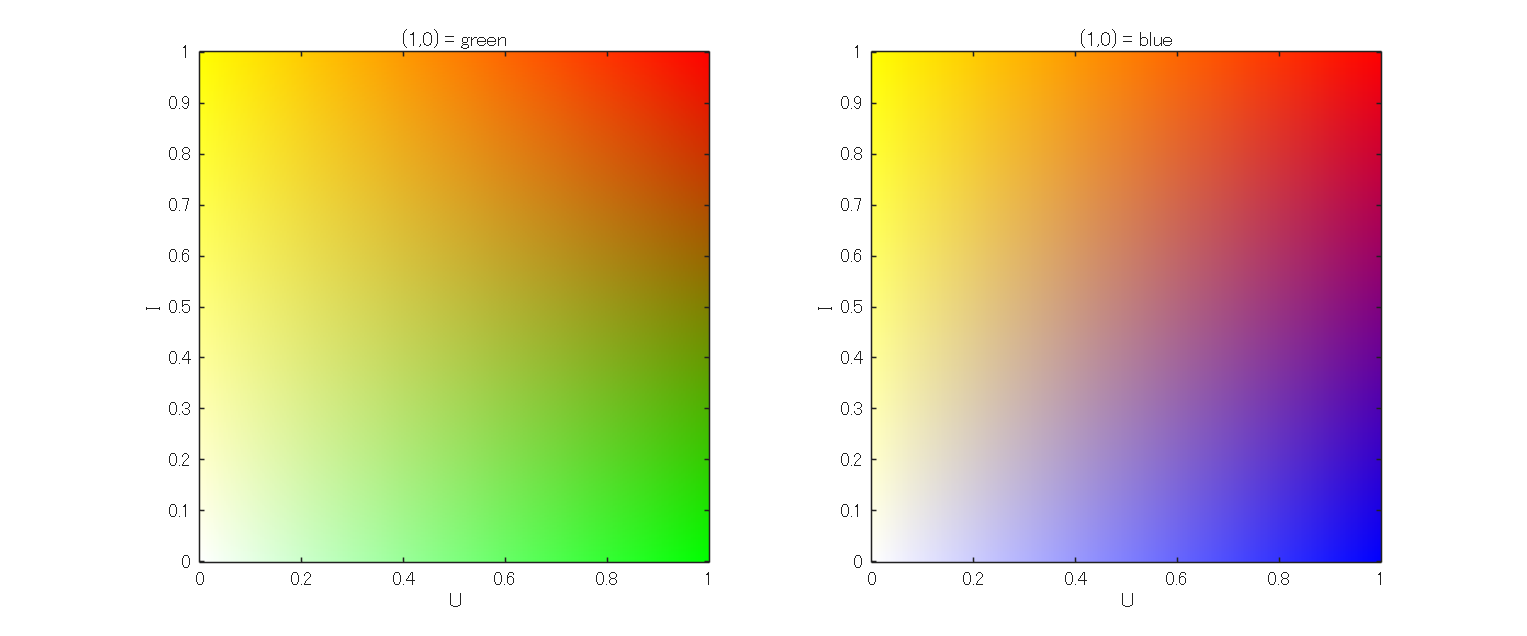

n = 301;
[U, I] = meshgrid(linspace(0,1,n), linspace(0,1,n));

%% Method 1: RGB bilinear, (1,0)=green
R1 = 1 - U + U.*I;
G1 = 1 - U.*I;
B1 = (1-U).*(1-I);
img1 = cat(3, R1, G1, B1);

%% Method 2: RGB bilinear, (1,0)=blue
C00 = [1,1,1]; % white
C01 = [1,1,0]; % yellow
C10 = [0,0,1]; % blue
C11 = [1,0,0]; % red

R2 = (1-U).*(1-I)*C00(1) + (1-U).*I*C01(1) + U.*(1-I)*C10(1) + U.*I*C11(1);
G2 = (1-U).*(1-I)*C00(2) + (1-U).*I*C01(2) + U.*(1-I)*C10(2) + U.*I*C11(2);
B2 = (1-U).*(1-I)*C00(3) + (1-U).*I*C01(3) + U.*(1-I)*C10(3) + U.*I*C11(3);
img2 = cat(3, R2, G2, B2);

%% Draw
figure('Color','w','Position',[100 100 1200 500]);

subplot(1,2,1);
image(linspace(0,1,n), linspace(0,1,n), img1);
set(gca,'YDir','normal');
axis square;
xlabel('U'); ylabel('I');
title('(1,0) = green');

subplot(1,2,2);
image(linspace(0,1,n), linspace(0,1,n), img2);
set(gca,'YDir','normal');
axis square;
xlabel('U'); ylabel('I');
title('(1,0) = blue');